# AFRL Linear Phased Array Simulation

Harris A. Ransom

11/13/2024

References:

- [https://www.mathworks.com/help/phased/ug/tapering-thinning-and-arrays-with-different-sensor-patterns.html](https://www.mathworks.com/help/phased/ug/tapering-thinning-and-arrays-with-different-sensor-patterns.html)

- [https://www.mathworks.com/help/phased/ug/plot-array-directivity-using-sensor-array-analyzer-app.html](https://www.mathworks.com/help/phased/ug/plot-array-directivity-using-sensor-array-analyzer-app.html)

### Uniform Linear Array (ULA) Modeling

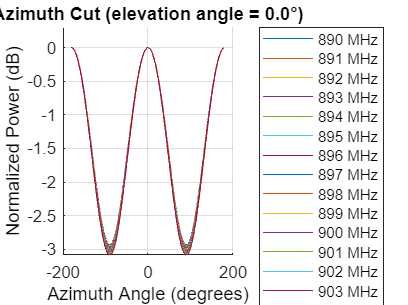

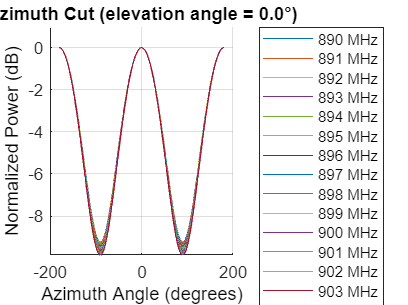

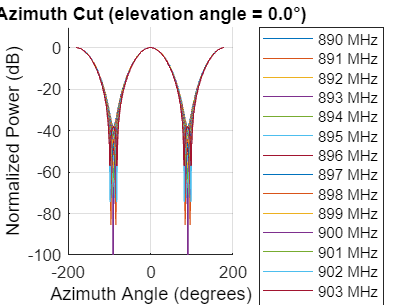

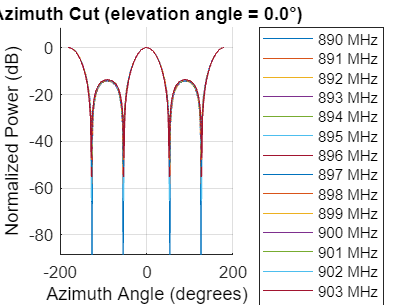

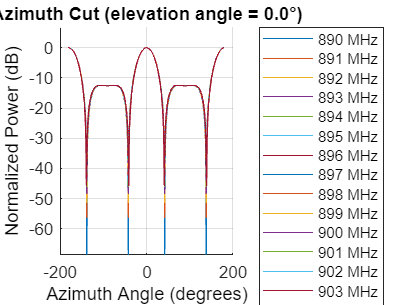

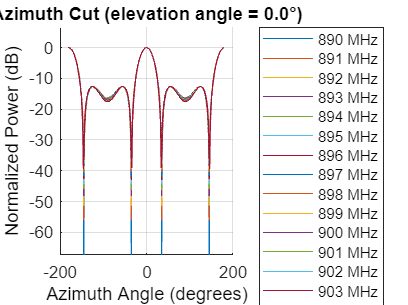

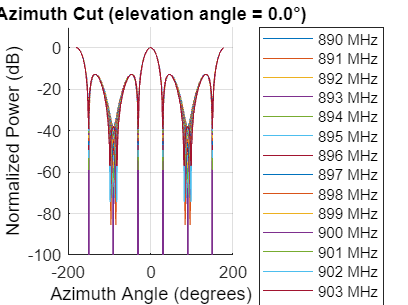

Nmax = 8;                    % Max number of elements to simulate
fc = 900e6;                  % Center operating frequency
BW = 10e6;                   % Bandwidth
c = 299792458;               % Speed of light
lambda = c / fc;             % Wavelength
halfWavelength = lambda / 2; % Half-wavelength
numPlots = 10;

% TODO: Plot figures as subplot groups
for i = 2:Nmax
    %for dist = linspace(0.01, halfWavelength, 10)
        % TODO: Vary distance
    %end
    dist = halfWavelength/2;

    titleVal = sprintf("Array%u", i);
    figure("Name", titleVal);
    hold on;
    for f = fc-BW:BW/numPlots:fc+BW
        array = phased.ULA(i, dist, 'Element', phased.IsotropicAntennaElement);
        %d = directivity(array,fc, ang, 'PropagationSpeed', c);
        pattern(array,f,-180:180,0,'PropagationSpeed',c,...
            'CoordinateSystem','rectangular',...
            'Type','powerdb','Normalize',true)
    end
end